# Trading Investment Strategy

## Clear workspace

clear; clc;


## Load Data

% readtimetable ("Trend Trading Input Output Data.xlsx", "Sheet","Price Data")
priceDS = datastore ("Trend Trading Input Output Data.xlsx","Sheets","Price Data")

priceDS =   SpreadsheetDatastore with properties:

                      Files: {
                             ' ...\Project-Repo-Test\Trend Trading Input Output Data.xlsx'
                             }
                    Folders: {
                             ' ...\kiki.mulyadi\Desktop\Matlab Investment R&D and Live\Project-Repo-Test'
                             }
   AlternateFileSystemRoots: {}
                     Sheets: 'Price Data'
                      Range: ''

  Sheet Format Properties:
             NumHeaderLines: 0
         VariableNamingRule: 'modify'
          ReadVariableNames: true
              VariableNames: {'Time', 'AALI', 'ABBA' ... and 663 more}
              VariableTypes: {'datetime', 'double', 'double' ... and 663 more}

  Properties that control the table returned by preview, <a href


prev = preview (priceDS)

% convert ds to tall table
priceTall = tall (priceDS);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).



% convert tall table to tall timetable

priceTall = table2timetable (priceTall);
head (priceTall)

ans =

  8×665 tall timetable

       Time        AALI     ABBA     ABDA     ABMM    ACES    ACST    ADES     ADHI     ADMF    ADMG    ADRO    AGAR    AGII     AGRO     AGRS     AHAP     AIMS     AISA      AKKU     AKPI    AKRA    AKSI    ALDO    ALKA    ALMI    ALTO    AMAG    AMAN    AMAR    AMFG    AMIN    AMOR


clear priceDS



Data cleaning

tic

priceTT = fillmissing (priceTall, 'previous');
priceTT = fillmissing (priceTT, 'next');
priceTT = gather (priceTT);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 3: Completed in 19 sec
- Pass 2 of 3: Completed in 25 sec
- Pass 3 of 3: Completed in 24 sec
Evaluation completed in 1 min 18 sec


priceTT = tall (priceTT);
head (priceTT)

ans =

  8×665 tall timetable

       Time        AALI     ABBA     ABDA     ABMM    ACES     ACST     ADES     ADHI     ADMF    ADMG    ADRO    AGAR    AGII     AGRO     AGRS     AHAP     AIMS     AISA      AKKU     AKPI    AKRA    AKSI     ALDO     ALKA    ALMI     ALTO     AMAG    AMAN    AMAR    AMFG    AMIN    AMOR



toc

Elapsed time is 104.357846 seconds.


Cumulative return

cumret = ret2tick (tick2ret (priceTT));
cumret = gather (cumret);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 3: Completed in 3.9 sec
- Pass 2 of 3: Completed in 2.7 sec
- Pass 3 of 3: Completed in 1.8 sec
Evaluation completed in 9.5 sec


cumretvar = cumret.Variables; 
cumretend = cumretvar (end,:);

cumretThreshold = 10;
buyidx = cumretend > cumretThreshold

buyidx = 1×665 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   1   0   0   1   0   0


cumretendHighValue = cumretend(buyidx)

cumretendHighValue =    32.5386   17.7885   19.3289   58.9595   10.6617   10.1260   11.5385   14.7727   11.1675   22.4762   25.7154   20.7227   12.9032   30.9589   17.8824   18.0000  113.7755   26.9880   13.1956   11.0734   11.6667   11.9608   19.9213   54.0541   11.4516   10.9797   18.3666   22.1217   17.0931   37.2703   16.7407   20.0000   12.0161   16.4667   47.4359   28.0000   34.1880   11.0185   26.3235   38.2166   17.2613   10.4483   18.8000


cumretendHighSymb = cumret.Properties.VariableNames (buyidx)

cumretendHighSymb = 1×43 cell array
    {'ABDA'}    {'AMRT'}    {'ARNA'}    {'ARTO'}    {'BRNA'}    {'CENT'}    {'CLEO'}    {'CPIN'}    {'CSMI'}    {'DCII'}    {'DEFI'}    {'DNET'}    {'EKAD'}    {'EMTK'}    {'ERTX'}    {'GEMA'}    {'GMTD'}    {'INAF'}    {'INDS'}    {'ITMA'}    {'JECC'}    {'JTPE'}    {'KAEF'}    {'KONI'}    {'MAPI'}    {'MARK'}    {'MREI'}    {'MTDL'}    {'MYOR'}    {'PSAB'}    {'PTDU'}    {'PTSP'}    {'SCMA'}    {'SKLT'}    {'SLIS'}    {'STTP'}    {'TCPI'}    {'TECH'}    {'TGKA'}    {'TOWR'}    {'TPIA'}    {'ULTJ'}    {'ZBRA'}



clear cumretvar cumret 


Selected variables

SelectedVarNames = cumretendHighSymb;
SelectedVarNames = sort (SelectedVarNames);
priceSample = priceTT (:, SelectedVarNames);
head (priceSample)

ans =

  8×43 tall timetable

       Time         ABDA     AMRT    ARNA     ARTO     BRNA      CENT     CLEO    CPIN    CSMI    DCII     DEFI      DNET     EKAD     EMTK     ERTX     GEMA    GMTD    INAF     INDS      ITMA     JECC    JTPE    KAEF    KONI    MAPI    MARK     MREI      MTDL      MYOR      PSAB     PTDU    

Build signal

% SMA 30
tic

WindowSize = 30;
priceSample = gather (priceSample);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 0.62 sec
Evaluation completed in 0.64 sec


priceSMA = movavg (priceSample,'simple', WindowSize);
head (priceSMA);


SMA_Signal= priceSample.Variables > priceSMA.Variables;
A = SMA_Signal;

SMA_Signal(2:end,:) = A(1:end-1,:);
SMA_Signal(1,:) = 0;

SMA_SignalTT = priceSample;
SMA_SignalTT.Variables = SMA_Signal;

toc

Elapsed time is 1.281933 seconds.


Transaction cost adjustment

tic

buyFee = 0.2/100;
sellFee = 0.3/100;

SMASignTemp = SMA_SignalTT.Variables;
SMA_SignalShiftOneBackward = SMA_SignalTT;
SMASignShiftTemp = SMA_SignalShiftOneBackward.Variables;

SMASignShiftTemp (1,:) = 0;
SMASignShiftTemp(2:end,:) = SMASignTemp (1:end-1,:);

SMA_SignalTT.Variables = SMASignTemp;
SMA_SignalShiftOneBackward.Variables = SMASignShiftTemp;

buyidx = SMA_SignalShiftOneBackward.Variables == 0 & SMA_SignalTT.Variables == 1 ;
buycost = SMA_SignalTT;
buycost.Variables = buyidx .*(1) .* buyFee;

tail (SMA_SignalTT);
tail (SMA_SignalShiftOneBackward);
tail (buycost);

sellidx = SMA_SignalShiftOneBackward.Variables == 1 & SMA_SignalTT.Variables == 0 ;
sellcost = SMA_SignalTT;
sellcost.Variables = sellidx .* (-1) .* sellFee;

tail (SMA_SignalTT);
tail (SMA_SignalShiftOneBackward);
tail (sellcost);

transactionCost = SMA_SignalTT;
transactionCost.Variables = buycost.Variables + sellcost.Variables;

tail (buycost);
tail (sellcost);
tail (transactionCost);

clear SMASignShiftTemp SMASignTemp SMA_SignalShiftOneBackward
clear priceSMA buyidx buycost sellidx sellcost

% SMA_Signal = tall (SMA_Signal); 

toc

Elapsed time is 0.145640 seconds.


Cumret for trading on each symbol 

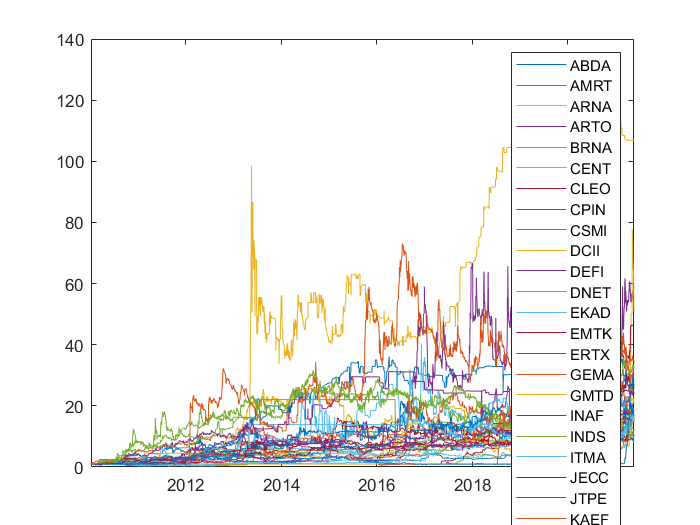

tic

retSym = tick2ret (priceSample);
netretsym = retSym;
transactionCostVariables = transactionCost.Variables;
netretsym.Variables = retSym.Variables + transactionCostVariables(2:end,:);

tail (SMA_SignalTT);
tail (retSym);
tail (netretsym);

cumretSym = ret2tick (netretsym);

plot (cumretSym.Time, cumretSym.Variables)
legend (cumretSym.Properties.VariableNames)


cumretSym = tall (cumretSym);
retSym = tall (retSym);

clear transactionCost transactionCostVariables

toc

Elapsed time is 2.051791 seconds.


Capital Allocation

tic 

% dailySignal = priceSample;
dailySignal = sum (SMA_SignalTT.Variables, 2);

dailySignalTT = timetable (priceSample.Time, dailySignal, 'VariableNames', "Daily Signal");

tail (dailySignalTT)

ans = 8×1 timetable
       Time        Daily Signal
    ___________    ____________

    06-May-2021         19     
    07-May-2021         20     
    10-May-2021         19     
    11-May-2021         18     
    17-May-2021         19     
    18-May-2021         17     
    19-May-2021         16     
    20-May-2021         16     



capitalAllocTreshold = 12;
capidx = dailySignal > capitalAllocTreshold;
capAlloc = double (capidx);

% Fill the capalloc
for i = 1:numel(dailySignal)
    capAlloc(i) = 1/(dailySignal(i));
    
end

capAlloc (capidx == 0) = 1/ capitalAllocTreshold;
max (capAlloc)

ans = 0.0833


capAllocTT = timetable (priceSample.Time, capAlloc, 'VariableNames', "Daily Cap Alloc");

toc

Elapsed time is 0.565317 seconds.


Capital Allocation Return-Adjusted

% Daily capital allocation per symbol
FinalSignal = SMA_SignalTT.Variables;
capAllocSym = FinalSignal;

for j= 1:size (FinalSignal, 2) 
  capAllocSym (:,j) = FinalSignal (:,j) .* capAlloc;
    
end

finalret = capAllocSym (2:end,:) .* gather (netretsym.Variables);


Portfolio daily return

dailyPortRet = zeros (size(priceSample.Variables,1),1) ;

dailyPortRet(2:end,:) = sum (finalret, 2);

dailyPortRetTT = timetable (priceSample.Time, dailyPortRet, 'VariableNames',"dailyPortRet");
dailyPortRetTT = tall (dailyPortRetTT);
cumRetPortfolio = ret2tick (dailyPortRetTT);
cumRetPortfolio = gather (cumRetPortfolio);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 0.58 sec
- Pass 2 of 2: Completed in 0.39 sec
Evaluation completed in 1.2 sec



tail (cumRetPortfolio)

ans = 8×1 timetable
       Time        dailyPortRet
    ___________    ____________

    06-May-2021       50.693   
    07-May-2021         51.3   
    10-May-2021       51.207   
    11-May-2021       50.564   
    17-May-2021       50.229   
    18-May-2021       49.931   
    19-May-2021       49.787   
    20-May-2021       49.859   


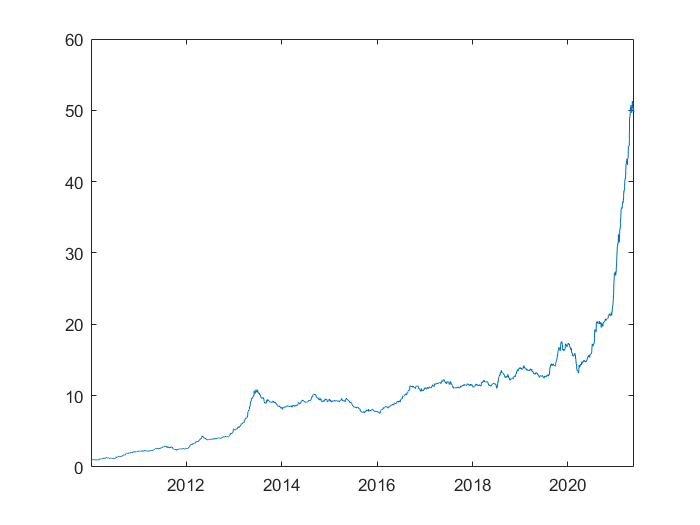


plot (cumRetPortfolio.Time, cumRetPortfolio.Variables)


A= cumRetPortfolio.Variables; 
cumRetPortfolioEndValue = A (end)

cumRetPortfolioEndValue = 49.8594


nDayPerYear = 252;
nYear = numel(A) / nDayPerYear ;
CAGR = ((cumRetPortfolioEndValue) ^(1/nYear))-1

CAGR = 0.4172


maxDD = maxdrawdown(cumRetPortfolio.Variables)

maxDD = 0.3086

SharpeRatio = sharpe (cumRetPortfolio.Variables)

SharpeRatio = 1.3474

Write to Excel

writetimetable (cumRetPortfolio, "Trend Trading Input Output Data.xlsx", ...
    'sheet', 'cumRetPortfolio');


save tradingdata.mat 
